# 1D Kalman Filtering

This example follows the Lecture note: 

Understanding the Basis of the Kalman Filter Via a Simple and Intuitive Derivation.

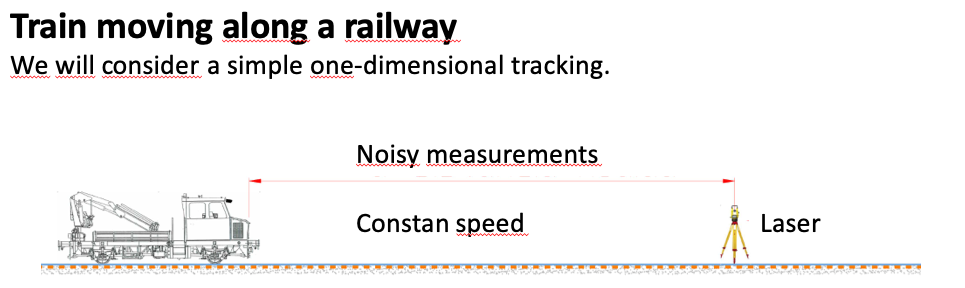

**The problem:** Predict the position and velocity of a moving  train 2 seconds ahead, having noisy measurements of its positions along the previous 10 seconds (10 samples a second)

The train is initially located at the point $x=0$ and moves along the $\hat X$ axis with constant velocity $\dot x=10 m/s$, so the motion equation of the train is: $\[{x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t\]$. Easy to see that the position of the train after 12 seconds will be x = 120m, and this is what we will try to find.

**Approach:** We measure (sample) the position of the train every $\Delta t=0.1[s]$ But, because of imperfect apparature, weather etc., our measurements are noisy, so the instantaneous velocity, derived from 2 consecutive position measurements, (remember, we measure only position) is innacurate. We will use Kalman filter as we need an accurate and smooth estimate for the velocity in order to predict train's position in the future.

We assume that the measurement noise is normally distributed $N(\mu,\sigma)$

close all
clear all

## Theoric Position 

Xtrue is a vector of true positions of the train 

Nsamples=100;
dt = 0.1;
t=0:dt:dt*Nsamples;
Vtrue = 10;
Xinitial = 0;
Xtrue = Xinitial + Vtrue * t;

## Motion equation


$${x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t\\ \dot x_k=\dot x_{k-1}$$


In matrix form


$$\left( {\begin{array}{*{20}{c}}
  {{x_k}} \\ 
  {{{\dot x}_k}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  1&{\Delta t} \\ 
  0&1 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  {{x_{k - 1}}} \\ 
  {{{\dot x}_{k - 1}}} 
\end{array}} \right) \to X_k= \Phi X_{k-1}$$


Xk = Phi*Xk_prev + Noise, that is Xk(n) = Xk(n-1) + Vk(n-1) * dt

Of course, velocity, ($\dot x$) is not measured, but it is estimated.  Phi ($\Phi$) represents the dynamics of the system: it is the motion equation.

Phi = [1 dt;
       0  1];

### Previous state 

Our initial guess is that the train starts at 0 with velocity that equals to 50% of the real velocity

Xk_prev = [0; 0.5*Vtrue];

### Current state estimate

Xk=[];

## Definitions 

### Error matrix 

Also confidence matrix. P states whether we should give more weight to the new measurement or to the model estimate.

sigma_model = 1;
P = [sigma_model^2 0;
     0 sigma_model^2];

### Process noise

Q is the process noise covariance. It represents the amount of uncertainty in the model. In our case, we arbitrarily assume that the model is perfect (no acceleration allowed for the train, or in other words - any acceleration is considered to be a noise)

Q = [0 0;
     0 0];

### Measurement matrix. 

M is the measurement matrix. We measure X, so M(1) = .  We do not measure V, so M(2)= 0

M = [1 0];

### Measurement noise covariance

 R is the measurement noise covariance. Generally R and sigma_meas can vary between samples. 

sigma_meas = 1; % 1 m/sec
R = sigma_meas^2;

## Kalman iteration

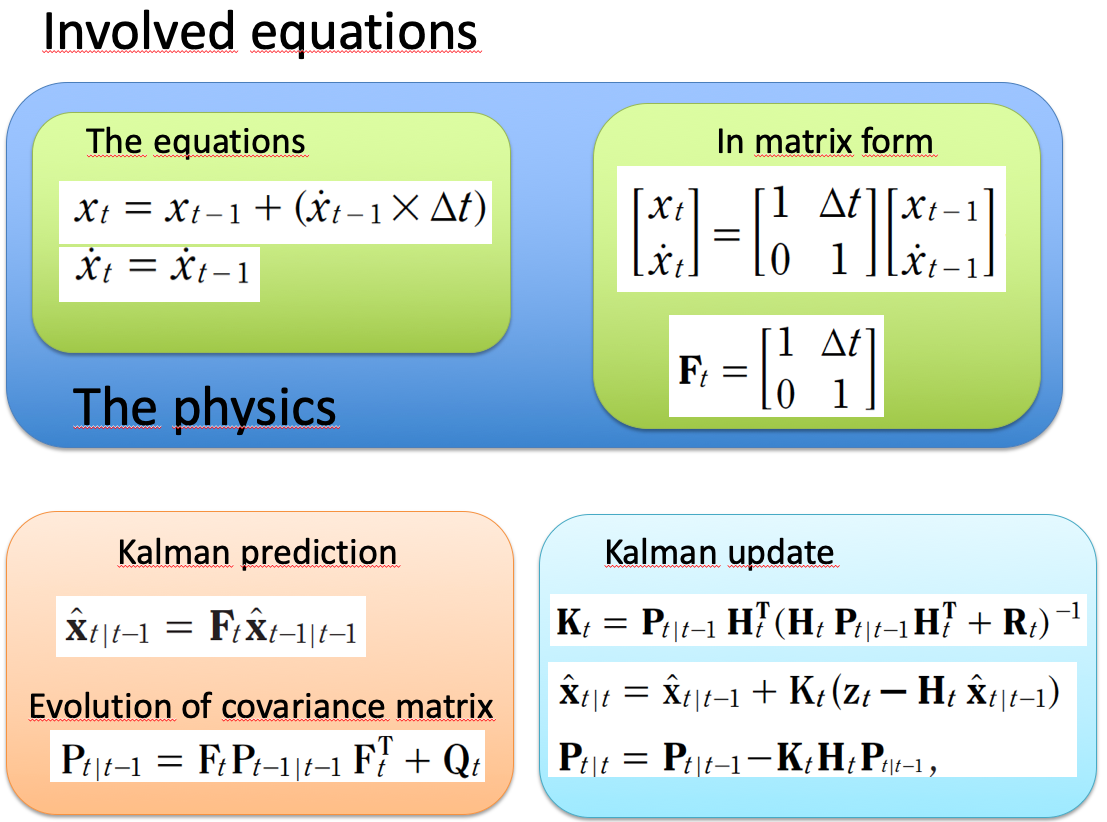

Buffers for later display

Xk_buffer = zeros(2,Nsamples+1);
Xk_buffer(:,1) = Xk_prev;
Z_buffer = zeros(1,Nsamples+1);

The loop

for k=1:Nsamples
    
    % Z is the measurement vector. In our
    % case, Z = TrueData + RandomGaussianNoise
    Z = Xtrue(k+1)+sigma_meas*randn; % It is a kind of data simulation
    Z_buffer(k+1) = Z;
    
    % Kalman iteration
    P1 = Phi*P*Phi' + Q; % Covariance stimated
    S = M*P1*M' + R; 
    
    % K is Kalman gain. If K is large, more weight goes to the measurement.
    % If K is low, more weight goes to the model prediction.
    K = P1*M'*inv(S);
    P = P1 - K*M*P1;
    
    Xk = Phi*Xk_prev + K*(Z-M*Phi*Xk_prev);
    Xk_buffer(:,k+1) = Xk;
    
    % For the next iteration
    Xk_prev = Xk; 
end;

## Plot resulting graphs

### Position analysis

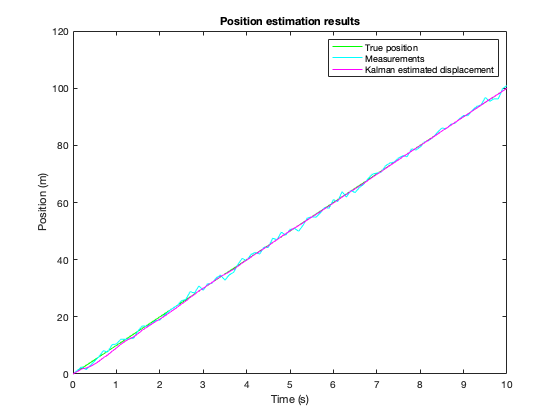

figure;
plot(t,Xtrue,'g');
hold on;
plot(t,Z_buffer,'c');
plot(t,Xk_buffer(1,:),'m');
title('Position estimation results');
xlabel('Time (s)');
ylabel('Position (m)');
legend('True position','Measurements','Kalman estimated displacement');

### Velocity analysis

The instantaneous velocity as derived from 2 consecutive position measurements

InstantaneousVelocity = [0 (Z_buffer(2:Nsamples+1)-Z_buffer(1:Nsamples))/dt];

The instantaneous velocity as derived from 5 consecutive position measurements

Go to help filter to undertand the coding.

WindowSize = 5;
b = (1/WindowSize)*ones(1,WindowSize);
a = 1;
InstantaneousVelocityRunningAverage = filter(b,a,InstantaneousVelocity);

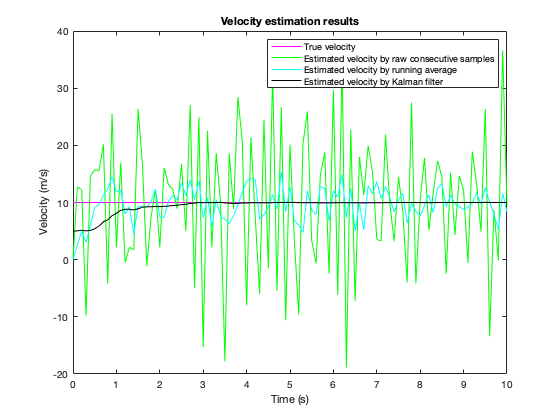

figure;
plot(t,ones(size(t))*Vtrue,'m');
hold on;
plot(t,InstantaneousVelocity,'g');
plot(t,InstantaneousVelocityRunningAverage,'c');
plot(t,Xk_buffer(2,:),'k');
title('Velocity estimation results');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend('True velocity','Estimated velocity by raw consecutive samples','Estimated velocity by running average','Estimated velocity by Kalman filter');

## Extrapolation 20 samples ahead

We take the last Nlast = 10 samples, and for each of these samples we try to see what would be the estimated position of the train at sample number Nsamples + SamplesIntoTheFuture if we took the position and the velocity that was known at that sample.

SamplesIntoTheFuture = 20;
Nlast = 10; % samples

### Theroric


$${x_k} = {x_{k - 1}} + {{\dot x}_{k - 1}}\Delta t$$


TruePositionInTheFuture = Xinitial + (Nsamples + SamplesIntoTheFuture) * Vtrue * dt;

### Averaging

ProjectedPositionByRunningAverage = Xk_buffer(1,(Nsamples+1-Nlast):(Nsamples+1)) + ...% last 11 sample from Kalman
                                    ((SamplesIntoTheFuture+Nlast):-1:SamplesIntoTheFuture) .* dt ... % vector time 
                                    .* InstantaneousVelocityRunningAverage((Nsamples+1-Nlast):(Nsamples+1)); % Avergage velocity

### Kalman ahead

ProjectedPositionByKalmanFilter = Xk_buffer(1,(Nsamples+1-Nlast):(Nsamples+1)) + ...% last 11 sample from Kalman
                                  ((SamplesIntoTheFuture+Nlast):-1:SamplesIntoTheFuture) .* dt ...% vector time 
                                  .* Xk_buffer(2,(Nsamples+1-Nlast):(Nsamples+1));

Plotting Positions

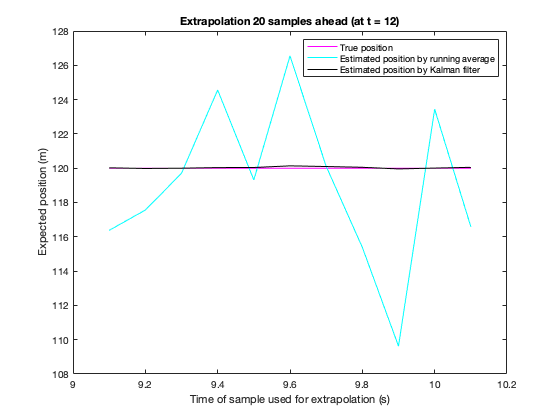

figure;
plot(((Nsamples+1-Nlast):(Nsamples+1))*dt,ones(size(1:11))*TruePositionInTheFuture,'m');
hold on;
plot(((Nsamples+1-Nlast):(Nsamples+1))*dt,ProjectedPositionByRunningAverage,'c');
plot(((Nsamples+1-Nlast):(Nsamples+1))*dt,ProjectedPositionByKalmanFilter,'k');
title(['Extrapolation 20 samples ahead (at t = ' num2str((Nsamples + SamplesIntoTheFuture) * dt) ')']);
xlabel('Time of sample used for extrapolation (s)');
ylabel('Expected position (m)');
legend('True position','Estimated position by running average','Estimated position by Kalman filter');